# การสร้างภาพ (visualization) ในโปรแกรม MATLAB

โดย อาจารย์ ธนัชชา ชูพจน์เจริญ

# Visualizaiton in MATLAB

Author :  Thanacha Choopojcharoen

Copyright : Thanacha Choopojcharoen

## จุดประสงค์

เอกสารนี้จัดทำขึ้นเพื่ออธิบายถึงการใช้งานขั้นพื้นฐานของโปรแกม MATLAB ซึ่งผู้เรียนสามารถ

- สร้าง plot จากข้อมูลที่หามาได้

- ปรับเปลี่ยนคุณลักษณะของ plot

- สร้าง animation เบื้องต้นจากข้อมูลเชิงเวลา 

## 1) พื้นฐานของการ plot และ axes

### 1.1) แนวการทำงานของ axes 

ในการสร้าง plot ใดๆนั้น โปรแกรม MATLAB จะทำสร้างไว้บนแผนภาพแกนที่เรียกว่า Axes และส่วนใหญ่แล้ว เรามักจะปรับเปลี่ยนตัว axes นั้นเพื่อปรับเปลี่ยนหน้าตาของ plot 

โดยเบื้องต้น เราไม่จำเป็นที่จะต้องสร้าง axes ต่างหาก เราสามารถที่จะเรียก plot ซึ่งจะทำการสร้าง axes ขึ้นมาใหม่อย่างอัตโนมัติ (โดยเบื้องต้น เราอาจจะไม่ต้องคำนึงถึง axes เลยก้ได้)

หากเรากำลังแสดง plot อยู่ function gca() จะทำหน้าที่อ่าน axes จาก plot นั้นซึ่งสามารถนำไปใช้ในการดัดแปลงในอนาคตได้ หรือเราสามารถที่จะสร้าง axes ขึ้นมา

หากเราทำการสร้าง axes แยกต่างหาก เราสามารุที่จะสร้างหลาย axes และดัดแปลงแต่ละ axes ได้ง่าย แทนที่จะต้องมาคอยเรียก gca ในแต่ละ plot ที่สร้างขึ้น

### 1.2) แนวการทำงานของ plot 

function plot() นั้นทำการวาดเส้นตรงให้เชื่อมต่อระหว่างคู่อันดับที่ระบุ ดังนั้น plot() ไม่สามารถใช้ในการวาดเส้นโค้งจริงๆได้ แต่ว่าตาของมนุษย์ไม่สามารถแยกแยะข้อแตกต่างระหว่างเส้นตรงหลายเส้นที่มีขนาดเล็กมากๆกับเส้นโค้ง ดังนั้น เราจึงใช้ plot() ในการประมาณภาพของเส้นโค้งใดๆก็ตามได้ (ถ้าระยะห่างระหว่างเส้นเล็กพอ) 

ดังนั้นเราสามารถใช้ plot() ในการวาดเส้นตรงธรรมดาได้เช่นกัน

### 1.2) การใช้งานเบื้องต้น

เราสามารถใช้งาน function plot() โดยใส่ input arguments ได้หลากหลายรูปแบบ แต่พื้นฐานแล้ว เราต้องใส่คู่อันดับที่ประกอบไปด้วยค่าในแกนแนวนอน และค่าในแกนแนวตั้ง

เราสังเกตได้ว่า ขนาดของ $t$ นั้นจะต้องเท่ากับ $y$ ในมิติที่สอดคล้องกัน

ตราบใดที่ข้อมูลทั้งสองชุดมีขนาดของมิติใดมิติหนึ่งที่เท่ากัน เราจะสามารถสร้าง plot ขึ้นมาได้พร้อมๆกัน

### 1.3) hold on และ hold off

หลักการในการดัดแปลงและควบคุม plot เป็นเรื่องที่ซับซ้อนและมีรายละเอียดมาก เราจะศึกษาดัดแปลง plot เบื้องต้นโดยเริ่มจากการพยายามที่จะ plot กราฟที่ละครั้ง

เราสังเกตได้ว่า มีแค่ plot สีน้ำเงินเท่านั้นที่ปรากฎ เนื่องจากว่า plot จะทำการลบ plot ก่อนหน้าที่ออกจาก figure  ถ้าหากเราต้องการให้ทั้งสอง plot อยู่ใน figure เดียวกัน เราสามารถ ใช้คำสั่ง hold on ได้

### 1.4) plot handle และ การลบ plot

บางครั้ง เราอาจต้องการที่จะลบ plot บางอันออกไปจาก axes หนึ่งในวิธีลบ plot คือการระบุ plot โดยใช้ plot handle 

เราสังเกตได้ว่า การลบ plot หยุด pause และสร้าง plot ใหม่ทำให้เกิดเป็นผลลัพธ์ที่คล้ายกับ animation ซึ่งนี่จะเป็นพื้นฐานของการทำ Animation แบบเบื้องต้น

### 1.5) การจัดการอื่นของ plot

เราสามารถปรับข้อมูลได้หลากหลาย ยกตัวอย่างเช่นดังต่อไปนี้

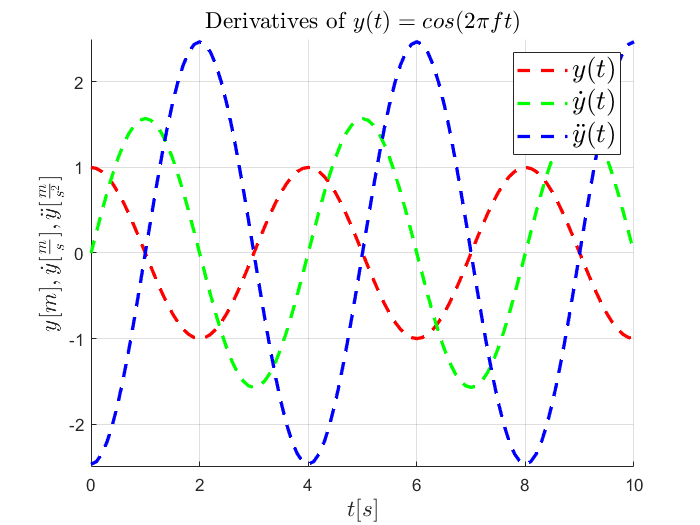

t_max = 10;
t = (0:0.1:t_max)';
T = 4;
f = 1/T;
w = 2*pi*f;
y = [cos(w*t) w*sin(w*t) -w^2*cos(w*t)];
clf;
ax = axes;
hold(ax,'on')
c = 'rgb';
for i = 1:3
    plot(ax,t,y(:,i),[c(i) '--'],'LineWidth',2) % ใส่สี รูปแบบเส้น และขนาดเส้น
end
grid(ax,'on')                  % ตีตาราง
xticks(ax,0:2:t_max)           % ขีดเส้น ตรงแกนแนวนอน
xticklabels(ax,0:2:t_max)      % ระบุค่าตรงแกนแนวนอน
xlabel(ax,'$t [s]$','interpreter','latex','FontSize',14) % เขียนระบุข้อมูลของแกนแนวนอน
yticks(ax,-3:3) 
yticklabels(ax,-3:3)
ylabel(ax,'$y [m], \dot{y} [\frac{m}{s}], \ddot{y} [\frac{m}{s^2}]$','interpreter','latex','FontSize',14)
% บอกข้อมูลของแต่ละ plot
legend({'$y(t)$','$\dot{y}(t)$','$\ddot{y}(t)$'},'interpreter','latex','FontSize',16)
% title ของ plot
title('Derivatives of $y(t)=cos(2\pi ft)$','interpreter','latex','FontSize',14)

### 1.6) การ plot หลาย axes หรือ subplot

บางครั้ง เราไม่ควรที่จะ plot ข้อมูลที่ไม่เกี่ยวข้องกันลงบน axes เดียวกัน แต่เราอาจจะนำมา plot ไว้ใกล้เคียงกัน ดังนั้นเราสามารถที่จะ plot ข้อมูลแต่ละอันได้โดยใช้ subplot

subplot เป็นการสร้าง axes ให้อยู่ในรูปแบบของตารางซึ่งเราต้องกำหนดขนาดของตาราง ($m$ แถว $n$ หลัก) โดยที่เราสามารถระบุตำแหน่งของ plot ในช่องตารางได้ดังต่อรูปแบบต่อไปนี้


$$\textrm{เลขที่ระบุตำแหน่งของ}\;\textrm{subplot}=\left\lbrack \begin{array}{cccc}
1 & 2 & \cdots  & n\\
n+1 & n+2 & \cdots  & 2n\\
\vdots  & \vdots  & \ddots  & \vdots \\
n\left(m-1\right)+1 & n\left(m-1\right)+2 & \cdots  & \textrm{mn}
\end{array}\right\rbrack$$


เราสามารถที่จะใช้ช่องตารางมากกว่าหนึ่งช่องในการ plot เช่นกัน

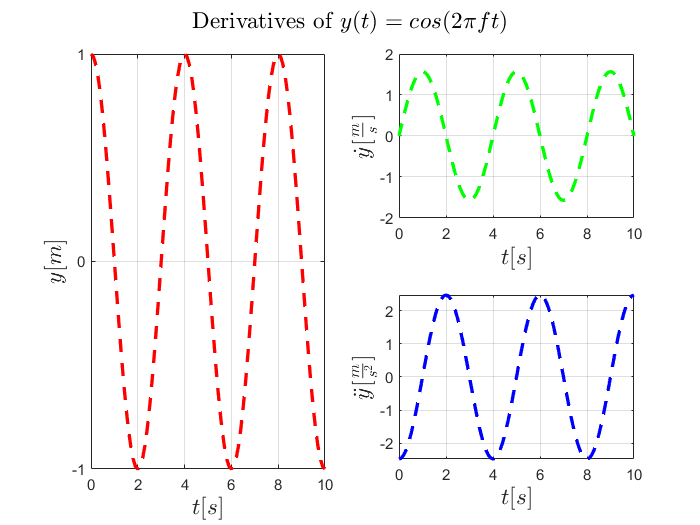

t_max = 10;
t = (0:0.1:t_max)';
T = 4;
f = 1/T;
w = 2*pi*f;
y = [cos(w*t) w*sin(w*t) -w^2*cos(w*t)];
clf;
m = 2;
n = 2;
ax_1 = subplot(m,n,[1 3]);
ax_2 = subplot(m,n,2);
ax_3 = subplot(m,n,4);
ax = [ax_1 ; ax_2 ; ax_3];
c = 'rgb';
label = {'$y [m]$','$\dot{y} [\frac{m}{s}]$','$\ddot{y} [\frac{m}{s^2}]$'};
for i = 1:3
    plot(ax(i),t,y(:,i),[c(i) '--'],'LineWidth',2) % ใส่สี รูปแบบเส้น และขนาดเส้น
    grid(ax(i),'on')                  % ตีตาราง
    xticks(ax(i),0:2:t_max)           % ขีดเส้น ตรงแกนแนวนอน
    xticklabels(ax(i),0:2:t_max)      % ระบุค่าตรงแกนแนวนอน
    xlabel(ax(i),'$t [s]$','interpreter','latex','FontSize',14) % เขียนระบุข้อมูลของแกนแนวนอน
    yticks(ax(i),-3:3) 
    yticklabels(ax(i),-3:3)
    ylabel(ax(i),label{i},'interpreter','latex','FontSize',14)
end
% title ของ plot
sgtitle('Derivatives of $y(t)=cos(2\pi ft)$','interpreter','latex','FontSize',14)

## 2) การสร้าง animation เบื้องต้น

Animation คือภาพที่ถูกฉายและเปลี่ยนทำให้ดูเหมือนกับว่าสิ่งของที่ปรากฎในภาพนั้นขยับอยู่ ยิ่งเราเปลี่ยนภาพได้เร็วมากเท่าไหร่ ผลที่ออกมาจะทำให้การเคลื่อนไหวดูสมจริงหรือเนียนมากขึ้น (smoother) จากแนวคิดนี้ เราสามารถสร้าง animation ได้โดยการใช้ for-loop กับ plot กับแบบจำลอง pendulum ดังต่อไปนี้


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}\;t}\left\lbrack \begin{array}{c}
\theta \\
\omega 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\omega \\
\frac{g}{l}\;\sin \left(\theta \right)-\frac{b}{m\;l^2 }\omega 
\end{array}\right\rbrack \\
g=9\ldotp 80665\;\left\lbrack \frac{\mathrm{m}}{{\mathrm{s}}^2 }\right\rbrack \\
l=1\;\left\lbrack \mathrm{m}\right\rbrack \\
m=1\left\lbrack \textrm{kg}\right\rbrack \\
b=0\ldotp 1\left\lbrack \frac{\textrm{kg}\cdot {\mathrm{m}}^2 }{\mathrm{s}}\right\rbrack \;
\end{array}$$


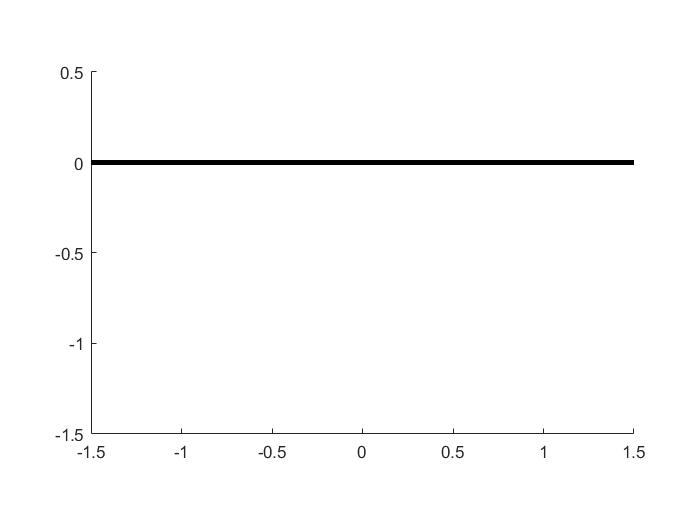

% สรา้งข้อมูลในการจำลอง
m = 1;
l = 1;
b = 1;
g = 9.80665;
t_max = 10;
x_0 = [pi/2;0];
[t,x] = ode45(@(t,x)[x(2);(g/l)*sin(x(1))-(b/(m*l^2))*x(2)],[0 t_max],x_0);

% เริ่มการทำ visualization
clf;
ax = axes;
hold(ax,'on');
axis(ax,'equal'); 
axis(ax,[-1.5 1.5 -1.5 0.5])
plot([-2 2],[0 0],'k','linewidth',3)


N = numel(t);
for i = 1:N-1
    theta = x(i,1);
    % วาดภาพ pendulum
    h = plot(ax,[0 l*sin(theta)],[0 l*cos(theta)],'b','linewidth',3);
    dt = t(i+1)-t(i);
    pause(dt)  % หยุดเป็นช่วงเวลา dt
    delete(h)
end
theta = x(end,1);
h = plot(ax,[0 l*sin(theta)],[0 l*cos(theta)],'b','linewidth',3);

ประเด็นสำคัญของการทำ animation นี้คือการที่เราหยุด pause เป็นระยะเวลาเท่ากับช่วงเวลาระหว่างแต่ละจุด ดังนั้นเราไม่สามารถที่จะ plot ได้ทุกตัว สิ่งที่เราทำได้คือ plot แค่ค่าแรกถึงค่าที่ N-1 และค่อย plot อีกครั้งข้างนอก for-loop

## โจทย์

### ข้อที่ 1

จากโจทย์ข้อที่ 2 ของ MATLAB_intro_6.mlx จงเขียน script ในการแสดงผลการเคลื่อนที่ของหุ่นยนต์ในรูปแบบของตาราง โดยที่

- ช่องที่เป็นกำแพง     เป็นสีดำ

- ช่องที่เป็นหุ่นยนต์    เป็นสีน้ำเงิน

- ช่องเริ่มต้น              เป็นสีเขียว

- ช่องสุดท้าย            เป็นสีแดง

- ช่องที่เป็นเส้นทาง   เป็นสีเหลือง

- ช่องอื่นๆ                 เป็นสีขาว

อาจจะมีบางจังหวะที่ช่องทับซ้อนกัน ดังนั้นเราจัดให้ความสำคัญของช่องเรียงตามที่ระบุไว้ข้างบน (หากหุ่นยนต์อยู๋บนเส้นทาง ให้ระบายช่องนั้นเป็นสีน้ำเงิน)

Animation จะถูกอัพเดททุกๆ 0.5 วินาที